clc
close all
clear

img1=imread( 'cameraman.tif' ); %reading cameraman image
img2=imread( 'rice.png' ); %reading rice image

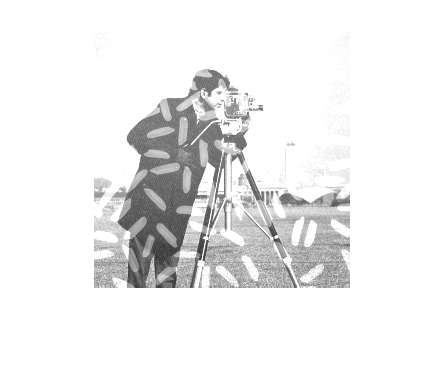

% adding the both images
imgadd=img1+img2; 
imshow(imgadd);       % displaying added image

% Subtracting both images
imgdiff=img1-img2 

imgdiff = 256×256 uint8 matrix
   34   67   63   56   56   49   70   68   62   48   67   63   79   73   67   64   57   72   36   56   42    0    0    0    0    0    0    0    0   35   56   55   65   59   47   74   50   67   62   65   71   55   74   64   70   77   78   67   60   74
   61   55   55   76   57   70   67   71   72   66   68   58   67   47   63   64   66   69   59   58    4    0    0    0    0    0    0    0    8   61   62   62   61   62   51   68   61   75   66   70   70   61   69   77   79   82   76   57   75   75
   59   52   55   69   60   64   66   62   61   65   58   38   64   57   71   62   57   67   61   44    0    0    0    0    0    0    0    0   60   58   63   65   74   58   59   67   60   70   64   79   65   67   77   54   70   81   76   72   83   58
   58   54   58   71   60   70   48   63   65   77   66   53   53   66   64   47   70   50   61   16    0    0    0    0    0    0    0   35   70   53   58   60   63   64   67   58   64   74   69   70   52   77   68 

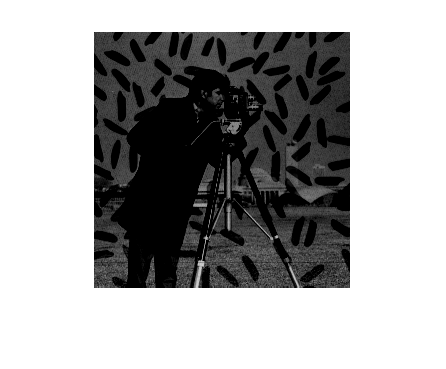

imshow(imgdiff);   % displaying subtracted image

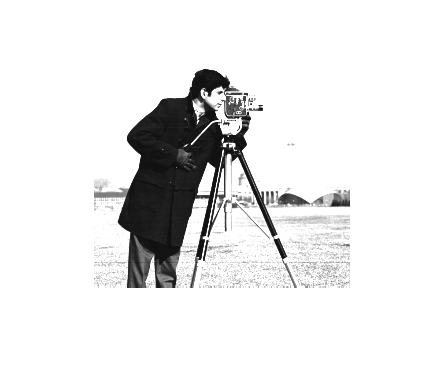

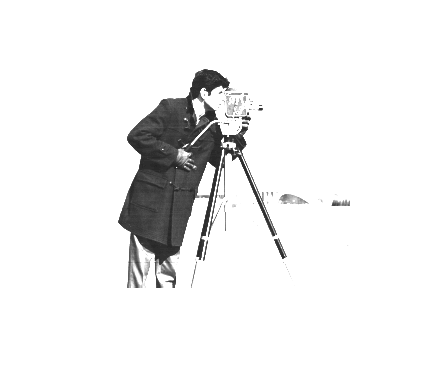

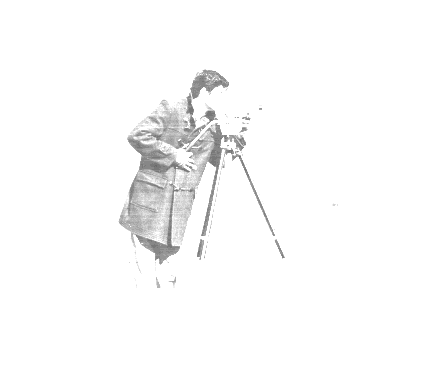

% displaying image with scalling factors 2,5 and 15
for i = [2,5,15]
    figure,imshow(img1*i);
end

img10=img1*10;

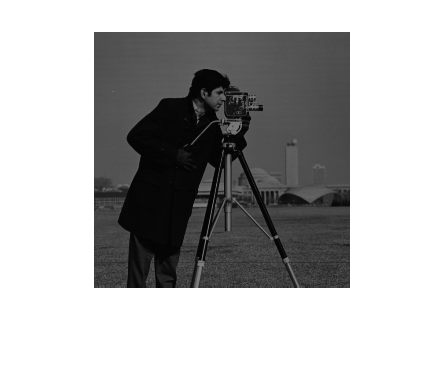

% dividing image by 2
imgdivby2=img1/2;
imshow(imgdivby2);

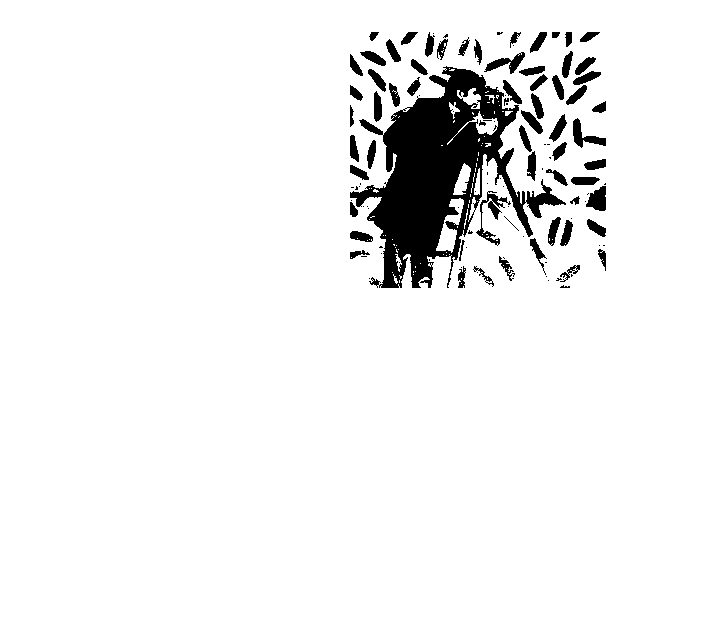

%Image formation from four different images
newimage=[512,512];
newimage(1:256,1:256)=imgadd;
newimage(1:256,257:512)=imgdiff;
newimage(257:512,1:256)=img10;
newimage(257:512,257:512)=imgdivby2;
imshow(newimage);